# Cargar información de NDVI RCAT

## Declaracion de variables sobre el área de estudio

import matlab.io.hdfeos.*

%clearvars -except area_estudio;
clear;
close all;

disp(">>> Declarando variables...ok")

>>> Declarando variables...ok



%directorio de datos
dir_data = "E:\DATA\";
producto = 'MOD13Q1';
archivo_kml = "Cultivo";

## **Obtener lista de archivos del producto**

info_hdf = f_infohdfs2table(dir_data,producto);

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1084 archivos


[num_registros_totales,~] = size(info_hdf);

% lon_mapa = [-98.8 -96.8];
% lat_mapa = [19.9 21.8];

lon_mapa = [-98.8 -96.8];
lat_mapa = [19.9 21.8];

% El ultimo parametro es el margen o umbral requerido para los datos NDVI
[coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam,ndvi_tam]...
    = f_get_coordinates(dir_data,archivo_kml,producto,info_hdf,0.28);

>>>>> Obteniendo la zona de estudio
E:\DATA\\MOD13Q1\061\*.hdf
>>>>> Analizando 1084 archivos


## Obtener matrices de latitud longitud

% Datos sin el disco duro
% info_hdf = f_infohdfs2table(dir_data,"MOD13Q1");
% Datos con el disco duro
% info_hdf = f_infohdfs2table("G:\DATA\","MOD13Q1");

if (num_registros_totales > 0)
    [lat,lon,ndvi]=f_get_latlon(info_hdf,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);
end

>>>>> Obteniendo latitud y longitud


## **Crear el área de estudio**

% crear matriz de 0 y 1 que delimitan el área de estudio
ae = exist("study_area","var");
if ae == 0  %% no existe
    ae = exist("study_area_"+archivo_kml+"_"+producto+".mat","file");
    if ae == 2
        disp(">>> Cargando área de estudio");
        load ("study_area_"+archivo_kml+"_"+producto);

        if( numel(study_area) ~= ( ndvi_tam(1)*ndvi_tam(2)) )
            disp("La variable area_estudio sera sustituida 1");
            study_area = f_create_study_area(dir_data+'KML\'+archivo_kml+'.kml',lat,lon);
            save ("study_area_"+archivo_kml+"_"+producto+".mat",'study_area');
        else
            disp(">>> Área de estudio existente 1");
        end

    else
        study_area = f_create_study_area(dir_data+'KML\'+archivo_kml+'.kml',lat,lon);
        save ("study_area_"+archivo_kml+"_"+producto+".mat",'study_area');
    end
else
    if( numel(study_area) ~= ( ndvi_tam(1)*ndvi_tam(2)) )
        disp("La variable area_estudio sera sustituida 2");
        study_area = f_create_study_area(dir_data+'KML\'+archivo_kml+'.kml',lat,lon);
        save ("study_area_"+archivo_kml+"_"+producto+".mat",'study_area');
    else
        disp(">>> Área de estudio existente 2");
    end
end

Creando área de estudio!!!


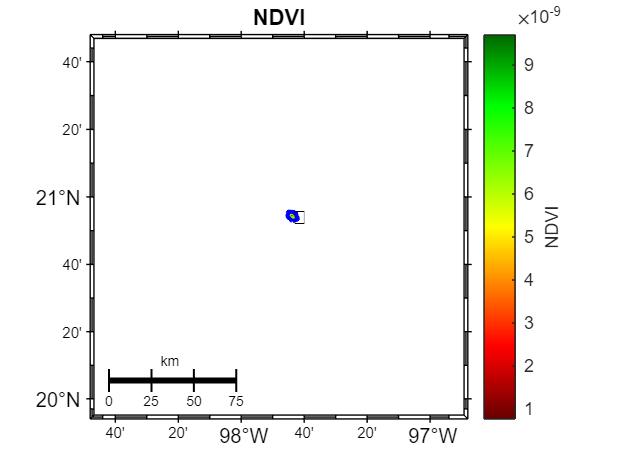



ndvi = double(ndvi) .* 0.0001;
ndvi(study_area==false)=nan;

f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi,"NDVI",[],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,2,'b',0);

## Leer los arreglos de datos

% Realizar la consulta de los datos que se requieren
tmp = find(  info_hdf.anio >= 2000 &  info_hdf.anio <= 2022);
info_consulta = info_hdf(tmp,:);

[num_registros,~] = size(info_consulta);


% arreglo 3d de ndvi por día
arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
% arreglo 3d para la calidad del pixel
arr_ndvi_re = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
% arreglo 3d para pixeles de buena calidad

arr_ndvi_nan = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
% arreglo 3d para pixeles completos
arr_ndvi_com = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);

bp=waitbar(0,'Obteniendo información de archivos MODIS'); 
for i=1:num_registros
    [ndvi,~,~,disponibilidad] = f_get_ndvi(info_consulta(i,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

    % recortar el area de estudio
    ndvi(study_area==false)=NaN;
    disponibilidad(study_area==false)=NaN;

     %almacenar en el arreglo en 3d
    arr_ndvi(:,:,i) = ndvi;
    arr_ndvi_re(:,:,i) = disponibilidad;
 
    %barra de progreso
    waitbar(i/num_registros,bp,sprintf('Obteniendo información de archivos MODIS (%3.0f%%) ',(i/num_registros*100)));
end
close(bp); 


bp=waitbar(0,'Generando series de tiempo con interpolación'); 
for i=1:ndvi_tam(1)
     for j=1:ndvi_tam(2)
         if study_area(i,j) == true
            arr_ndvi_nan(i,j,:) = f_rm_pixel_baja_calidad(arr_ndvi(i,j,:),arr_ndvi_re(i,j,:));
            arr_ndvi_com(i,j,:) =  f_fillmissing_linear(arr_ndvi_nan(i,j,:),0);
         end

     end
     waitbar(i/ndvi_tam(1),bp,sprintf('Generando series de tiempo con interpolación (%3.0f%%) ',(i/ndvi_tam(1)*100)));
end
close (bp);



% for i=1:num_registros
%    % Mostrar algun registro
% idx=11;
% 
% %     f_draw_map(lon_mapa,lat_mapa,lon,lat,arr_ndvi(:,:,idx),"NDVI "+idx,[],"NDVI","NDVI");
%     f_draw_map(lon_mapa,lat_mapa,lon,lat,arr_ndvi_re(:,:,idx),"NDVI "+idx,[],"NDVI","NDVI");
% % end

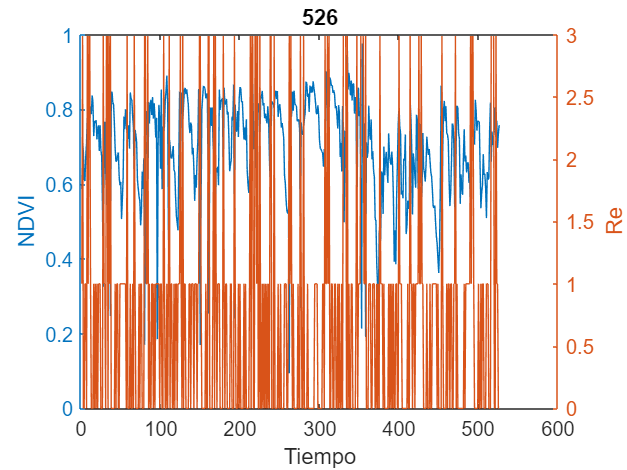


serie = reshape(arr_ndvi(20,20,:),[],1);
% confiabilidad de los datos releabilyti
serie_re = reshape(arr_ndvi_re(20,20,:),[],1);

figure;

yyaxis left 
plot(serie);
title(length(serie))
xlabel('Tiempo')
ylabel('NDVI')
yyaxis right
plot(serie_re);
ylabel('Re')


malos=serie_re(serie_re>=3);
disp("Pixeles Anomalos: "+length(malos));

Pixeles Anomalos: 69


## **Promedio**

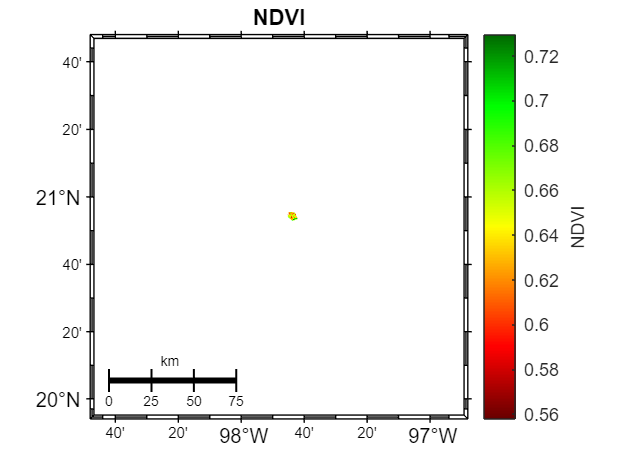

figure;
promedio_ndvi=f_mean_3dpp(arr_ndvi);
f_draw_map(lon_mapa,lat_mapa,lon,lat,promedio_ndvi,"NDVI",[],"NDVI","NDVI");

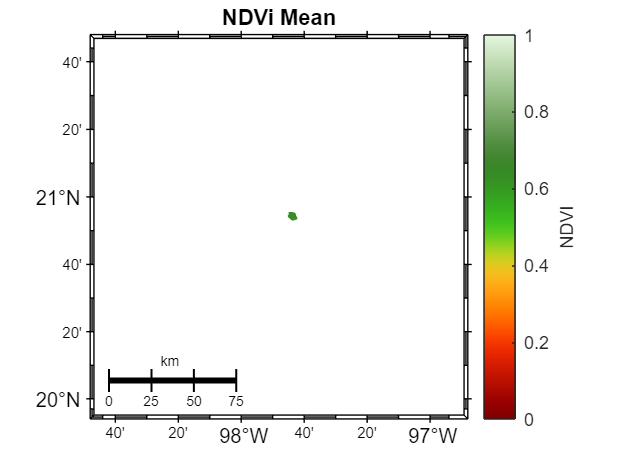


figure;
% Parametros que se reciben
% 5-Titulo del mapa
% 6-Rango del ndvi
% 7-color
% 8-Titulo barra

f_draw_map(lon_mapa,lat_mapa,lon,lat,promedio_ndvi,"NDVi Mean",[0 1],flipud( m_colmap('chloropy',256)),"NDVI" );


figure;


### **Calculo Minimos Maximos y desviacion standar**

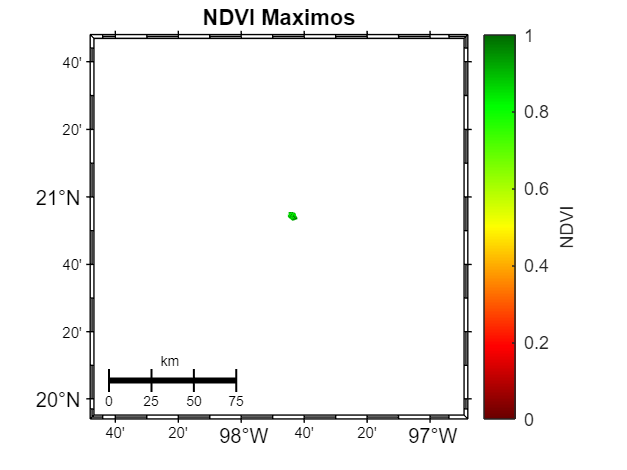

max_ndvi=f_max_3dpp(arr_ndvi);

f_draw_map(lon_mapa,lat_mapa,lon,lat,max_ndvi,"NDVI Maximos",[0 1],"NDVI","NDVI");

min_ndvi=f_min_3dpp(arr_ndvi);

f_draw_map(lon_mapa,lat_mapa,lon,lat,min_ndvi,"NDVI Minimos",[0 1],"NDVI","NDVI");

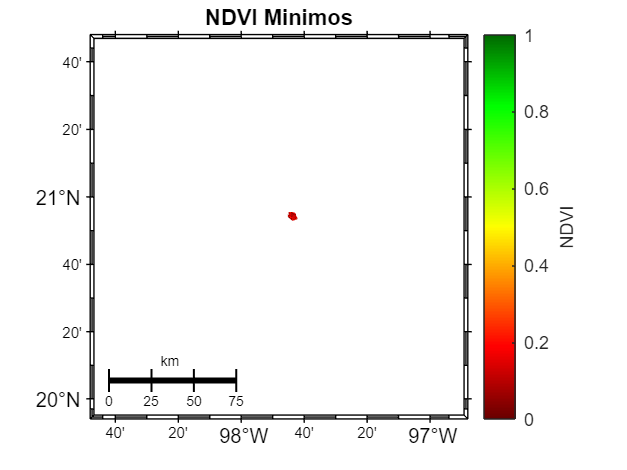

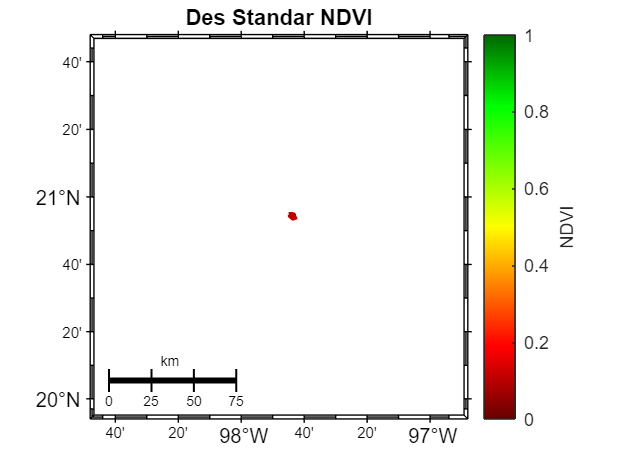



std_ndvi=f_std_3dpp(arr_ndvi);

% f_draw_map(lon_mapa,lat_mapa,lon,lat, std_ndvi,"Desviación Standar NDVI",[0 1],flipud(m_colmap('chloropy',256)),"NDVI");
f_draw_map(lon_mapa,lat_mapa,lon,lat, std_ndvi,"Des Standar NDVI",[0 1],"NDVI","NDVI");

Regresion lineal serie temporal


[a0,a1,ajuste]=f_reglin(1:length(serie),serie')

a0 = 0.7305

a1 = -1.1241e-04

ajuste =     0.7304    0.7302    0.7301    0.7300    0.7299    0.7298    0.7297    0.7296    0.7295    0.7293    0.7292    0.7291    0.7290    0.7289    0.7288    0.7287    0.7286    0.7284    0.7283    0.7282    0.7281    0.7280    0.7279    0.7278    0.7277    0.7276    0.7274    0.7273    0.7272    0.7271    0.7270    0.7269    0.7268    0.7267    0.7265    0.7264    0.7263    0.7262    0.7261    0.7260    0.7259    0.7258    0.7256    0.7255    0.7254    0.7253    0.7252    0.7251    0.7250    0.7249


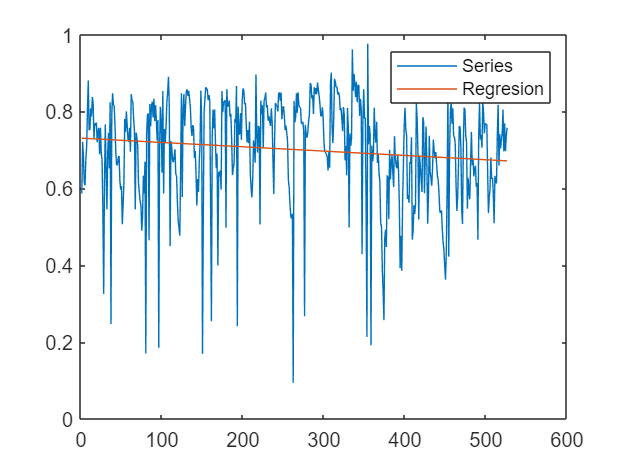

% 1- x cantidad de elementos 
% 2- y 
% 3- x cantidad de elementos
% 4- y elementos de y en regresion lineal
plot(1:length(serie),serie,1:length(serie),ajuste);
legend(["Series" "Regresion"]);

% plot(1:length(serie),serie,1:length(serie),ajuste);
v24 = a0+a1*24

v24 = 0.7278

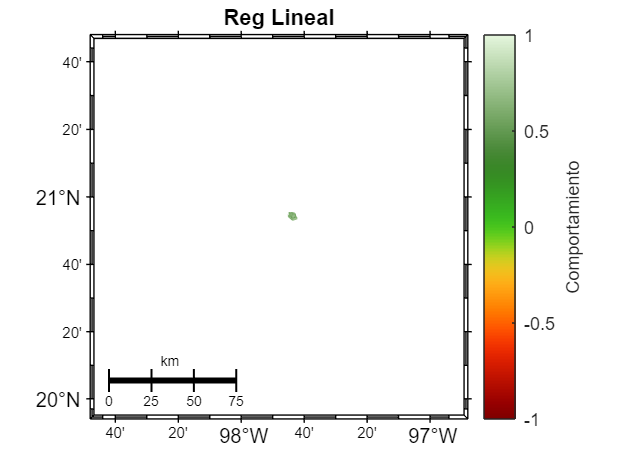

datos=f_reglin_3dpp(arr_ndvi);

figure;

f_draw_map(lon_mapa,lat_mapa,lon,lat,datos,"Reg Lineal",[-1 1],flipud(m_colmap('chloropy',256)),"Comportamiento");

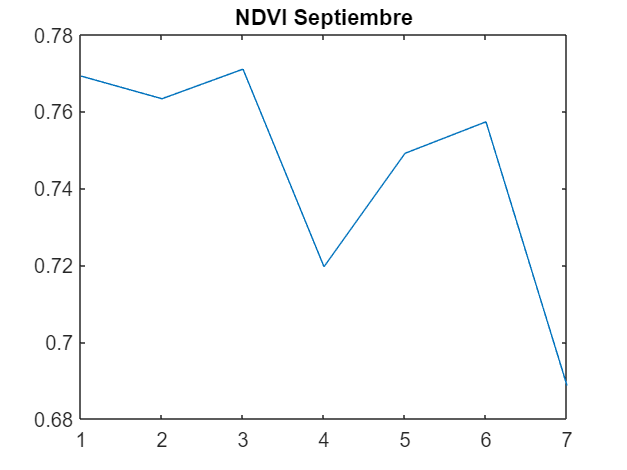


% for i=17:23
%     f_draw_map(lon_mapa,lat_mapa,lon,lat,arr_ndvi(:,:,i) ,"NDVI"+i,[-1 1],"NDVI","NDVI");
%     figure;
% end

serie_cosecha = reshape(arr_ndvi(20,20,17:23),[],1);
plot(1:7,serie_cosecha');
title('NDVI Septiembre')

x=info_hdf;
% Calculando datos de septiembre
septiembre=find(info_hdf.mes==9);
datos=info_hdf(septiembre,:);

Promedio por año NDVI

init= 2003 %info_hdf.anio(1)

init = 2003

finish= 2023 %info_hdf.anio(size(info_hdf,1))

finish = 2023

% mes=[];
% ps_1=[];
eage_temp=[];
mean_eage=[];
pivot=1;
eage_x=[];
for i=init:finish
    eage_temp{pivot}=find(info_hdf.anio==i);
    mean_eage(pivot)=mean(arr_ndvi(:,:,eage_temp{pivot}),"all","omitnan");
    eage_x(1,pivot)=i;
    pivot=pivot+1;
end

Index in position 3 exceeds array bounds. Index must not exceed 526.

% Graficando promerio por año 
plot(eage_x,mean_eage);
title('Promedio NDVI','2003 - 2022')


Calculo de NDVI Promedio por mes ()

promedio_mes_ndvi=[];
idx_ea=2;
for mes=1:12
    for eag=init:finish
        indx_month=find(info_hdf.anio==eag & info_hdf.mes==mes);
        promedio_mes_ndvi(mes,1)=mes;
        promedio_mes_ndvi(mes,idx_ea)=mean(arr_ndvi(:,:,indx_month),"all","omitnan");
        idx_ea=idx_ea+1;
    end
    idx_ea=2;
end


Grafica promedios

mes=5;
plot( eage_x,promedio_mes_ndvi(mes, 2:end));

Unrecognized function or variable 'eage_x'.

title('Promedio NDVI', "mes:"+mes);


Analisis por municipio (selecciona municipio de 1-10)

format long;
idx_municipio=10;
plot(eage_x,datos_prod(idx_municipio).Superficie_sembrada_Ha);
hold on;
plot(eage_x, datos_prod(idx_municipio).Superficie_cosechada_Ha);
title(datos_prod(idx_municipio).Municipio);
legend("Sembrado", "Cosechado","Location","south");
hold off
plot(eage_x, datos_prod(idx_municipio).Valor_Prod)
title(datos_prod(idx_municipio).Municipio,'Valor de Produccion');


All Municipios

Promedio valor produccion

tam=size(datos_prod,2);
valor_prod=zeros(10,20);
for i=1:tam
    valor_prod(i,:)=datos_prod(i).Valor_Prod;
end
mean_val_prod=mean(valor_prod);
plot(eage_x, mean_val_prod);
title("Valor Produccion",'Pronedio')

Superficie cosechada


tam=size(datos_prod,2);
valor_cocecha=zeros(10,20);
for i=1:tam
    valor_cocecha(i,:)=datos_prod(i).Superficie_cosechada_Ha;
end
mean_val_cosecha=mean(valor_cocecha);
plot(eage_x, mean_val_cosecha);
title('Prmedio ',"Cocecha")



Correlacion

mean_eage;
mean_val_prod;

scatter(mean_val_prod,mean_eage);

correlation=corrcoef(mean_val_prod,mean_eage);
corr_value=correlation(1,2) ;
% text(1, 8, ['Correlación: ', num2str(corr_value)], 'FontSize', 12);
grid on;


% format short;
sprintf( '%.6f', valor_prod(10,20))

TEST

format short
sum(valor_prod,2)


